# **線形化モデルの導出**

**本ファイルでは電力系統モデルの近似線形化システムを計算します。**

作業フロー上での対応箇所は以下の赤枠で示した部分です。

# 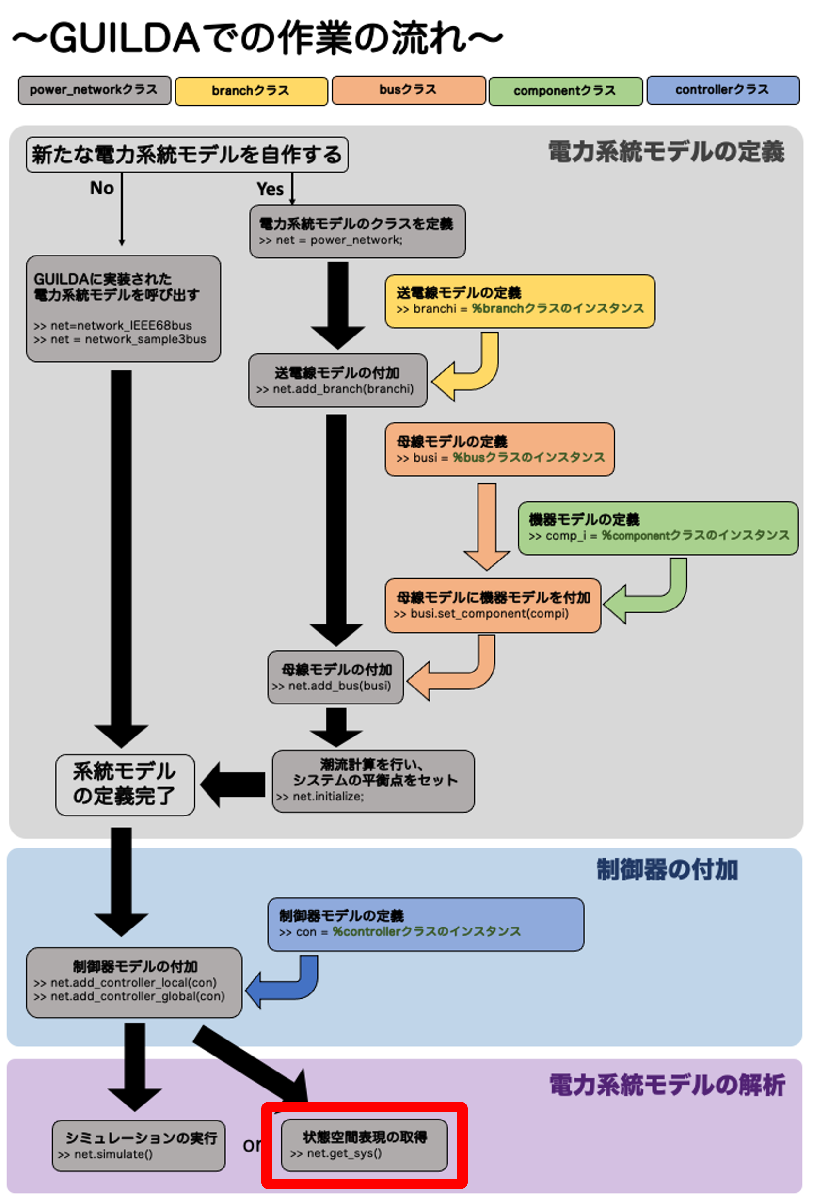

まず、システムの線形化をしていくにあたりシステムを定義します.

ここでは68busの電力システムを例として以下のように定義します.

net = network.IEEE68bus();

# **１. 近似線形化システムの状態空間表現について**

後述しますがGUILDAでは以下のようにして近似線形化システムを取得することができます。

sys = net.get_sys();

この関数では電力システムを以下の式の様な状態空間表現に線形化します .


$$\begin{array}{l}
\dot{x} =A\left(x-x^* \right)+B\left(u-u^* \right)\\
y=C\left(x-x^* \right)+D\left(u-u^* \right)
\end{array}$$


なお上の式で表される状態・入力・出力の定義は、1軸発電機モデルを例に取ると以下のようになります. 当然、機器が変わると状態等も変わりますので、注意してください。以下の説明において、発電機とある場合には、すべて1軸発電機を指していると解釈してください。

### **・****状態 **x

        １つの発電機につき状態パラメータが７つ存在します．あるi番目の発電機の状態をxiとすると、

            
$$x_i =\left\lbrack \begin{array}{c}
\delta_i \\
\Delta \omega_i \\
E_i \\
V_{\textrm{fdi}} \\
\xi_{1i} \\
\xi_{2i} \\
\xi_{3i} 
\end{array}\right\rbrack$$


        と表され、上から順に

-     回転子偏角δ

-     周波数偏差Δω

-     発電機の内部電圧E

-     AGCの状態変数Vfd(1つ)

-     PSSの状態変数ξ(3つ)を指します. この状態Xiを用いて、発電機が全部で$I_G$個あるとき、

            
$$X=\left\lbrack \begin{array}{c}
X_1 \\
\vdots \\
X_{I_G } 
\end{array}\right\rbrack$$


        としたものが上の式で状態Xとして定義されています。

### **・****入力 u**

        いま対象の電力システムのバスのうち発電機がつながった母線と負荷がつながった母線の個数の合計を$I_{\textrm{GL}}$、発電機がつながった母線の個数を$I_G$とすると、

            
$$u=\left\lbrack \begin{array}{c}
u_1 \\
\vdots \\
u_{I_{\textrm{GL}} } \\
d_1 \\
\vdots \\
d_{I_G } 
\end{array}\right\rbrack \cdots \left(\star \right)$$


        が入力uとして定義されています. (★)の要素となる$u_i$と$d_i$は次のような入力になります。

                **▶︎ ****uiについて**

                 発電機に対する入力か、負荷に対する入力かでuiの中身は変わります。

                    **発電機**

                            入力は２つ存在し、i番目の発電機への入力は以下のようになります。

                            
$$u_i =\left\lbrack \begin{array}{c}
u_{\textrm{avr}}^{\left(i\right)} \\
u_{\textrm{governor}}^{\left(i\right)} 
\end{array}\right\rbrack$$


                            ただし、$u_{\textrm{avr}}$はAVRからの入力で、$u_{\textrm{governor}}$はgovernorを介したAGCからの入力を示しています。

                            なお、AVRが接続されていない発電機は$u_{\textrm{avr}}$が０になります。

                    **負荷**

                            入力は２つ存在し、i番目の負荷への入力は

                            
$$u_i =\left\lbrack \begin{array}{c}
u_1^{\left(i\right)} \\
u_2^{\left(i\right)} 
\end{array}\right\rbrack$$


                            のようにかけます。 ただし、これらの入力は、元の負荷のアドミタンスを$Y_{\textrm{ori}}$としたとき、アドミタンスYが

                            
$$Y=\textrm{Re}\left(Y_{\textrm{ori}} \right)\times \left(1+u_1 \right)+\mathit{\mathbf{j}}\;\textrm{lm}\left(Y_{\textrm{ori}} \right)\times \left(1+u_2 \right)$$


                            で時間変化するように、それぞれアドミタンスの実部と虚部の増加割合を示しています。

                **▶︎ ****diについて**

                    外乱を表す変数になります。 制御系の設計時に外乱を印加する際に使用します。単にシミュレーションを行う場合は不要です。 

                    外乱を使う場合は、入力ベクトルuの要素として入れていることからも分かる通り、外部入力として外乱を入れることになることに注意してください。 

                    i番目の機器に加わる外乱の数がn個であるとすると、

                        
$$d_i =\left\lbrack \begin{array}{c}
d_1^{\left(i\right)} \\
\vdots \\
d_n^{\left(i\right)} 
\end{array}\right\rbrack$$


                    と表されます。 (★)では外乱は$d_1 \sim d_{I_G }$となっており、発電機にのみ加わっているように書いてあります。

                    これは、発電機に加わる外乱に比べると負荷に加わる外乱は小さいので無視しているということを意味しています。 

                    負荷にも外乱を入れる場合は、外乱を表すベクトルdの要素数も変わるので外乱に関するシステム行列Rも辻褄が合うように定義し直す必要があります。

### **︎・****出力y**

    出力変数yの各行は以下の変数をさしている。

- **各発電機の状態変数 (x)**： 各７要素←状態xの場合の７つの変数と同じです

- **発電機の評価関数 (z)** : 各１要素←制御系を設計するときに評価基準とする変数です

- **各バスでの電圧の値(Vreal,Vimage)** : 各2要素(実部と虚部の情報)

- **各バスでの電流の値(Ireal,Iimage) **: 各2要素(実部と虚部の情報)対象の電力システムのバスのうち全バスの個数をIall、発電機のつながった母線の個数をIGとすると、

                        
$$y = \pmatrix{x_1 \cr \vdots \cr x_{I_{G}} \cr z_1 \cr \vdots \cr z_{I_{G}} \cr V_1 \cr \vdots \cr V_{I_{all}} \cr I_1 \cr \vdots \cr I_{I_{all}}}$$


                という構成になっている。なお各ViとIiはフェーザ表示で表されるため、

                
$$V_i =\left\lbrack \begin{array}{c}
V_{\textrm{real}} \\
V_{\textrm{image}} 
\end{array}\right\rbrack ,I_i =\left\lbrack \begin{array}{c}
I_{\textrm{real}} \\
I_{\textrm{image}} 
\end{array}\right\rbrack$$


                と２変数ずつ格納されています.

# **２. 関数get_sysの実行**

with_controller = false;
sys =  net.get_sys(with_controller);

get_sysで得られるシステムは平衡点からの偏差を状態としてとっていることに注意してください．

### **・****入力引数 ：**`with_controller`

`    with_controller`の値が`true`の場合はコントローラが付加されたシステム，`false`の場合はコントローラなしのシステムを返す．規定値は`false`です。

- `true`にする場合コントローラーの設定をしておく必要があります。コントローラの定義についての詳細は[Step2_AddController.mlx](matlab:open('./Step2_AddController.mlx'))を参照してください。

### **・****出力変数 ：**`sys`

    出力された変数sysの中には以下のような変数が格納されています。

    GUILDAでは近似線形化したシステムをmatlab buildinのssクラスとして返します。各フィールドの詳細は[公式ドキュメント](https://jp.mathworks.com/help/control/ref/ss.html)を参照してください

        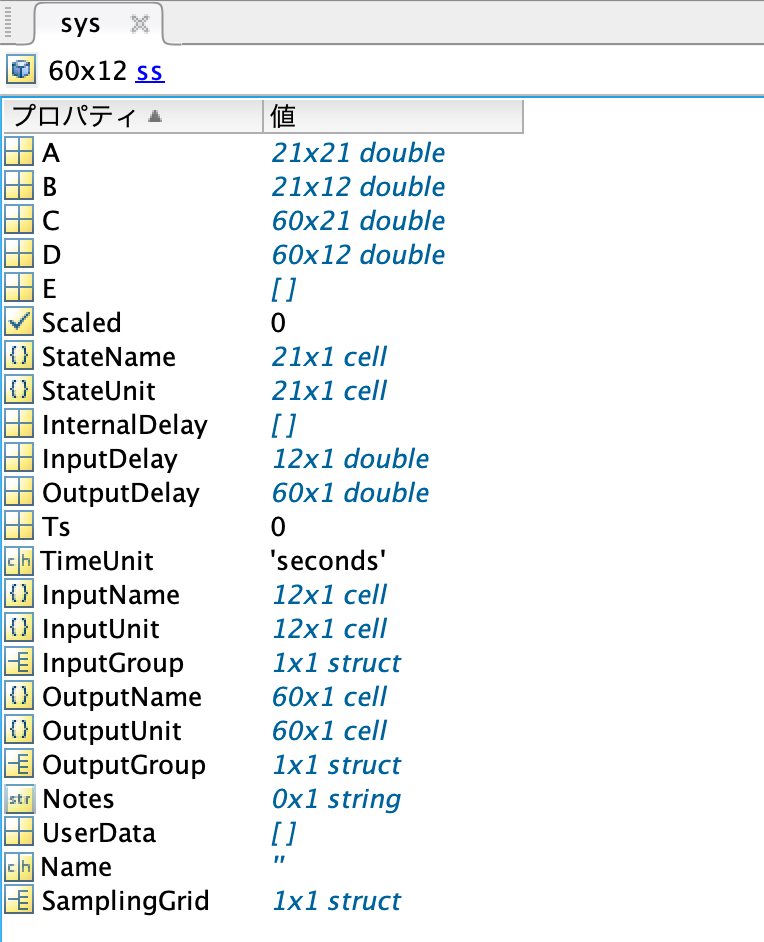

        いかに主要なフィールドをいくつか取り上げて開設します。

####         ・**状態方程式の係数行列**`A,B,C,D`

            線形化したシステムの状態行列A,入力行列B,出力行列C,直達行列Dの各要素の情報を格納しています.

####         ・**入力情報**I`nputGroup`

            状態空間方程式の入力ベクトルuの各チャンネル名と何番目のチャンネルに対応するかの情報を格納しています。

####         ・**出力情報**`OutputGroup`

            状態空間方程式の出力ベクトルyの各チャンネル名と何番目のチャンネルに対応するかの情報を格納しています。

            `get_sys`の返り値は`sys`としていますが、当然違う名前を宛てることもできます。 

            以降では、`sys`という変数名を返り値にしたと仮定しますが、違う名前を設定した場合にはその都度変換して考えてください。

# **３. 線形化したシステムのシュミレーションの実行**

線形化したシステムのシュミレーションは以下のように行います。

out = net.simulate([0 20], 'linear', true);

`linear`の直後に`true`とした場合はシステムを線形化してシミュレーションを行い、`false`とした場合は線形化を行わずにシュミレーションを行います.

それ以外の変数の設定や実行については、シミュレーション実行の[Step4_SimulateCondition.mlx](matlab:open('./Step4_SimulateCondition.mlx'))に示されている`net.simulate(t,option)`と同様であるため，そちらを参照してください.

# **４. コード例**

## ⅰ. コントローラーを追加する

sys =  net.get_sys(true);

この関数を実行するにはnetクラスの中にすでにコントローラーの情報が格納されている必要があります.

予め実装されている`power_network`のインスタンスを用いている場合、そのクラスの内部にはすでにブロードキャストのコントローラーなどが定義されています。それに加えてレトロフィットコントローラーなどを追加して定義しておくと、それらのコントローラを含めたシステムの状態空間方程式を導出させることができます。コントローラの設定については制御器付加の[Step2_AddController.mlx](matlab:open('./Step2_AddController.mlx'))を参照してください.

なお、`get_sys(false)`とするとコントローラーを除いたシステムの状態空間方程式を導出するということになります.

## ⅱ. 特定の入力から出力までのシステムを見る

返数のsysに格納されているA行列B行列C行列D行列はバスの個数によっても大きさが変動し、本チュートリアルで扱っている電力システムも68個のバスによるシステムであり、その状態方程式は膨大な要素数を持つ行列方程式です. ここでは、そのシステムの中から特定の入力から特定の出力までの一部分だけのシステムを抽出する方法を示します. 例えば入力u1から出力V1までのシステムを見たい場合，以下のように実行することで見ることができます.

sys('V1','u1')

## ⅲ. 線形化したシステムのシミュレーション結果を見る

以下のコードは68busシステムを線形化し，その出力をグラフで表示するものです。ここでは2種類のサンプルコードを紹介します。

まず1つ目のコードは、地絡応答についての応答を線形化を行ってシュミレーションしたプロットに、`get_sys`を用いて得られた状態空間モデルをもとに、`initial()`関数を用いて時間応答を求めたものを重ねたものです。下の結果を見ると2つの時間応答が一致していることがわかります。なお`initial()`は[Control System Toolbox]に標準搭載されている関数です。

 
net= network.IEEE68bus();
opt = {'linear',true,'report','none'};
% 地絡時の応答結果を出力
out_fault = net.simulate([0,0.01],'fault',{{[0,0.01],1}},opt{:});

tend = 5;

% 地絡終了時の状態を初期値としてシミュレーション

    % GUILDAのsimulateメソッドで応答計算
    x0 = tools.hcellfun(@(x) x{end,:}, out_fault.X)';
    out_linear = net.simulate([0 tend],'x0_sys',x0,opt{:});

    % GUILDAのget_sysメソッドで得られた線形システムからビルドイン関数initialで応答計算
    sys = net.get_sys();
    x0 = x0 - net.x_equilibrium;
    [z, t, x] = initial(sys, x0);
    numele = size(find(t<tend), 1);
    z = z(1:numele, :);
    t = t(1:numele, :);
    x = x+net.x_equilibrium';
    x = x(1:numele, :);

% ２つの応答結果を比較
figure
for i = 1:16
    subplot(4,4,i)
    p = plot(out_linear.t, out_linear.X{i}{:, 2}, '-', t, x(:, 7*(i-1)+2), '--');
    p(1).LineWidth = 2;
    p(2).LineWidth = 2; 
    subtitle(['@component',num2str(i)], 'Interpreter', 'tex');
    ylabel('\Delta\omega ')
    legend('GUILDA','initial')
end

2つめコードは１つめと同様に地絡応答についてのシュミレーションですが、ここでは同じネットワークシステム、同じ地絡条件のもとで線形化シュミレーションと非線形のままのシュミレーションの結果を比較するコードとなっています。出力結果は下のとおりです。

 
net = network.IEEE68bus();
opt = {'fault',{{[0,0.01], 1}}, 'report','none'};

out_nonlinear = net.simulate([0,5], 'linear',false, opt{:});
out_linear    = net.simulate([0,5], 'linear', true, opt{:});

figure
for i = 1:16
    subplot(4,4,i)
    p = plot(out_linear.t,    out_linear.X{i}{:, 2}, '-',...
             out_nonlinear.t, out_nonlinear.X{i}{:, 2}, '--');
    p(1).LineWidth = 2;
    p(2).LineWidth = 2;
    title(['@component',num2str(i)], 'Interpreter', 'tex');
    ylabel('\Delta\omega')
    legend('linear','nonlinear')
end

`お疲れ様でした！！`

`以上でTutorialは終了です。本Tutorialでは基本的なGUILDAの使用方法の紹介を行いました。`

[](matlab:open('./Step5_SimulateResultData.mlx'))　　